# Thermal model

clear all; clc; close all;

## Constants

EH2 = 285840;           %[J/mol] internal energy of hydrogen
F = 96485;              %Faraday Constant
R = 8.3145;             %ideal gas constant [J/K/mol]
ncell = 20;             %number of cells in the stack
CtoK = 273.15;          %Kelvin To Celcius conversion constant
V0_theory_datasheet = 1.48;     %reversible stack potential
Tamb = 21;              %^oC
Vtank = 1.6;            %m^3
bar_to_Pa = 100000;     % 1 bar = 100000 Pa
Qcool = 0;              %No cooling

## Import data

to_import = ["eff1","eff2","eff3","eff4","eff5","step1","step2","err1","err2","err3"];

m = struct("control",[])

m = struct with fields:
    control: []


m.time = [];
m.I_stack = [];
m.U_stack = [];
m.T_in = [];
m.T_out = [];
m.tankP = [];
m.cooling = [];
m.Ph2o = [];
m.Po2 = [];
m.Ph2 = [];
m.Tamb = [];
for c = 1:length(to_import)
    tdms = TDMS_getStruct(convertStringsToChars(to_import(c)+ ".tdms"))
    measurements = tdms.Group1;
    m(:).control = [m.control measurements.Control.data];
    m(:).time = [m.time measurements.Time.data];
    m(:).I_stack  =[m.I_stack measurements.I_Stack.data];
    m(:).U_stack = [m.U_stack measurements.U_Stack.data];
    m(:).T_in = [m.T_in measurements.O2_T_In.data];
    m(:).T_out = [m.T_out measurements.O2_T_Out.data];
    m(:).tankP = [m.tankP measurements.H2_PrProd.data];
    m(:).cooling = [m.cooling measurements.Cooling_.data];
    m(:).Ph2o = [m.Ph2o measurements.H2O_PrStackIn.data];
    m(:).Po2 = [m.Po2 measurements.O2_PrStackOut.data];
    m(:).Ph2 = [m.Ph2 measurements.H2_PrSys.data];
    m(:).Tamb = [m.Tamb measurements.Cabinet_T.data];
    fprintf(c + ".tdms")
end

tdms = struct with fields:
     Props: [1×1 struct]
    Group1: [1×1 struct]


1.tdms

tdms = struct with fields:
     Props: [1×1 struct]
    Group1: [1×1 struct]


2.tdms

tdms = struct with fields:
     Props: [1×1 struct]
    Group1: [1×1 struct]


3.tdms

tdms = struct with fields:
     Props: [1×1 struct]
    Group1: [1×1 struct]


4.tdms

tdms = struct with fields:
     Props: [1×1 struct]
    Group1: [1×1 struct]


5.tdms

tdms = struct with fields:
     Props: [1×1 struct]
    Group1: [1×1 struct]


6.tdms

tdms = struct with fields:
     Props: [1×1 struct]
    Group1: [1×1 struct]


7.tdms

tdms = struct with fields:
     Props: [1×1 struct]
    Group1: [1×1 struct]


8.tdms

tdms = struct with fields:
     Props: [1×1 struct]
    Group1: [1×1 struct]


9.tdms

tdms = struct with fields:
     Props: [1×1 struct]
    Group1: [1×1 struct]


10.tdms

m(:).T = (m.T_in+m.T_out)./2; %average stack temp.

firstrun_idx = m.time>1000 & m.time<6300;
all_run = m.time>2000 & m.time<16000;
automode_idx = m.control == 2;
automode_times = m.time(m.control == 2);
validsamples = m.I_stack > 10 & m.time>2000 & m.time<16500; 

### Plot the experiment

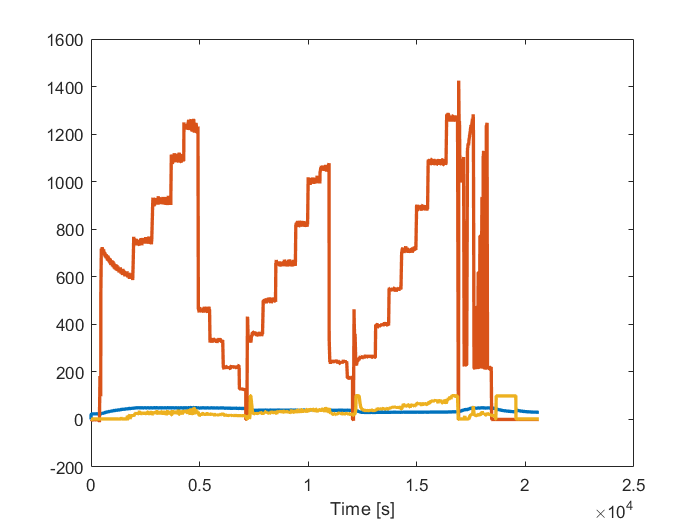

m.PowerIn = m.U_stack .* m.I_stack;
m.Qloss = m.PowerIn .* (1-EH2.*ncell./(2.*m.U_stack.*F));
figure;
plot(m.time,[m.T;m.Qloss;m.cooling],"LineWidth",2)
xlabel("Time [s]")

#### Prepare timeseries data for the simulation

cth_begin = 400;
cth_end = 16000;
cth_measurements = m.time > cth_begin & m.time<cth_end;
Qloss = timeseries(m.Qloss(cth_measurements),m.time(cth_measurements));
RealTemp = timeseries(m.T(cth_measurements),m.time(cth_measurements));
T_amb =  timeseries(m.Tamb(cth_measurements)+CtoK,m.time(cth_measurements));
T_cool = ones(length(m.time(cth_measurements)),1); T_cool(1:7355) = 50; T_cool(7356:12215) = 40; T_cool(12215:end) = 30;
Tcool = timeseries(T_cool,m.time(cth_measurements)-cth_begin); %The cooling setting that we adjusted during the experiment

## Cth

cth_measurements = m.time > 200 & m.time<1600;

#### Plot experiment for Cth

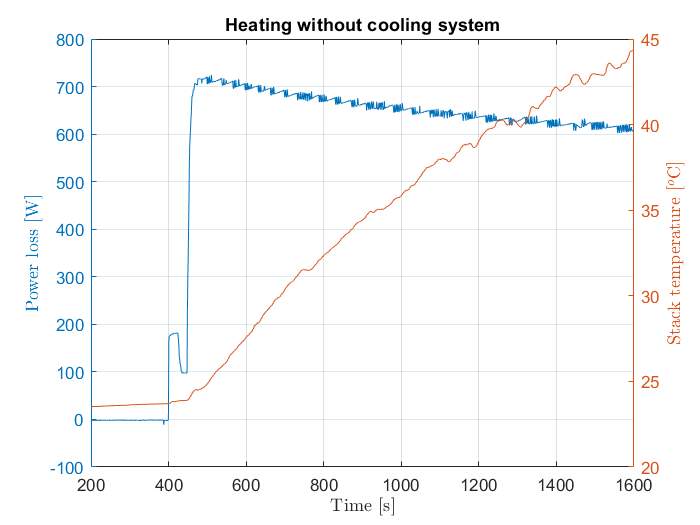

figure;
yyaxis left
plot(m.time(cth_measurements),m.Qloss(cth_measurements))
ylabel("Power loss [W]","Interpreter","latex")
hold on
yyaxis right
ylabel("Stack temperature [$^o$C]","Interpreter","latex")
plot(m.time(cth_measurements),m.T(cth_measurements))
xlabel("Time [s]","Interpreter","latex")
title("Heating without cooling system")
grid on
hold off

#### Calculate Cth

cth_calc = m.time > 435 & m.time<800;
temp_cth = m.T(cth_calc);
Cth = trapz(m.Qloss(cth_calc), m.time(cth_calc))./(temp_cth(end)-temp_cth(1))

Cth = 2.9347e+04

#### Calculate Rth using simulations

Rth = 0.1

Rth = 0.1000

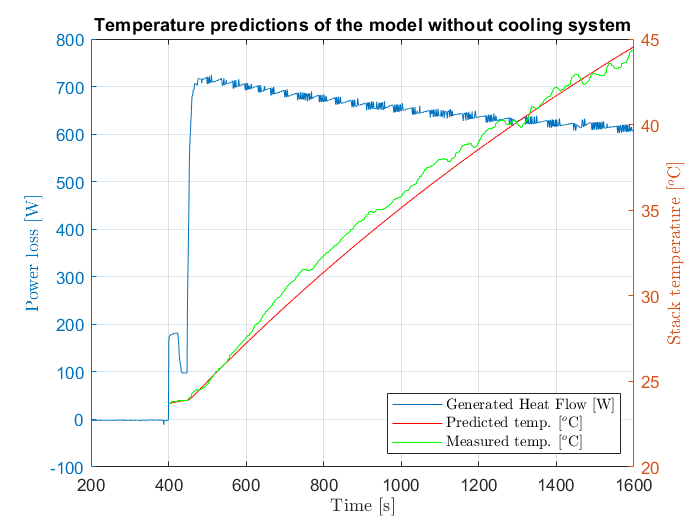

output = sim("Thermal_model.slx");

figure;
yyaxis left
plot(m.time(cth_measurements),m.Qloss(cth_measurements))
ylabel("Power loss [W]","Interpreter","latex")
hold on
yyaxis right
ylabel("Stack temperature [$^o$C]","Interpreter","latex")
plot(output.Model_Temp_Sim,"r")
plot(output.Real_Temp_Meas,"g-")
xlim([200 , 1600])
xlabel("Time [s]","Interpreter","latex")
title("Temperature predictions of the model without cooling system")
grid on
hold off
legend("Generated Heat Flow [W]","Predicted temp. [$^o$C]","Measured temp. [$^o$C]","location","southeast","interpreter","latex")

#### Verify Rth and Cth on heating during operation

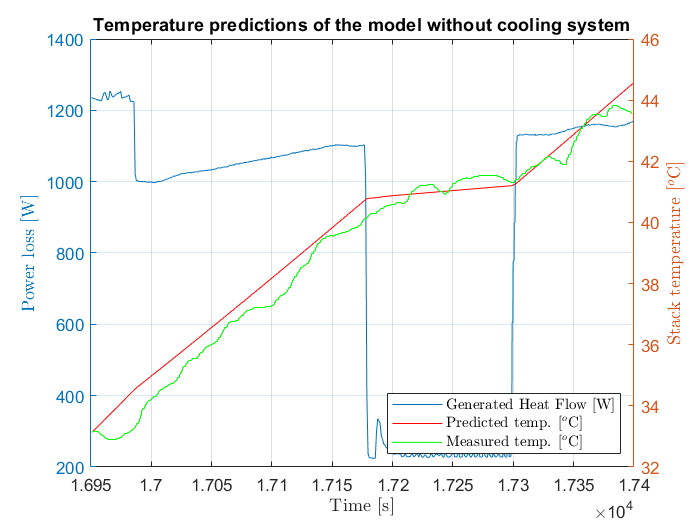

cth_begin = 16950;
cth_end = 17400;
cth_measurements = m.time > cth_begin & m.time<cth_end;
Qloss = timeseries(m.Qloss(cth_measurements),m.time(cth_measurements));
RealTemp = timeseries(m.T(cth_measurements),m.time(cth_measurements));
T_amb =  timeseries(m.Tamb(cth_measurements)+CtoK,m.time(cth_measurements));
T_cool = 50*ones(length(m.time(cth_measurements)),1);% T_cool(1:7355) = 49; T_cool(7356:12215) = 40; T_cool(12215:end) = 30;
Tcool = timeseries(T_cool,m.time(cth_measurements)-cth_begin); %The cooling setting that we adjusted during the experiment

output = sim("Thermal_model.slx");

figure;
yyaxis left
plot(m.time(cth_measurements),m.Qloss(cth_measurements))
ylabel("Power loss [W]","Interpreter","latex")
hold on
yyaxis right
ylabel("Stack temperature [$^o$C]","Interpreter","latex")
plot(output.Model_Temp_Sim,"r")
plot(output.Real_Temp_Meas,"g-")
xlabel("Time [s]","Interpreter","latex")
title("Temperature predictions of the model without cooling system")
grid on
hold off
legend("Generated Heat Flow [W]","Predicted temp. [$^o$C]","Measured temp. [$^o$C]","location","southeast","interpreter","latex")

## Cooling system

#### Plot experiment for cooling system

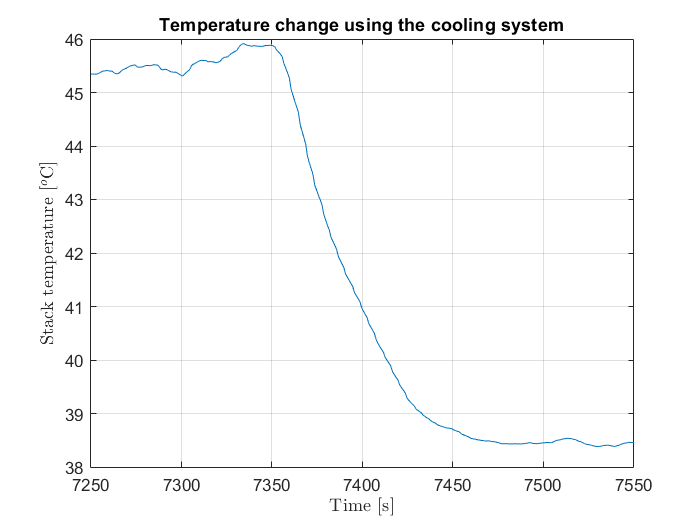

figure;
plot(m.time,m.T)
xlabel("Time [s]","Interpreter","latex")
ylabel("Stack temperature [$^o$C]","Interpreter","latex")
title("Temperature change using the cooling system")
grid on
xlim([7250 7550])

#### Simulate with cooling system

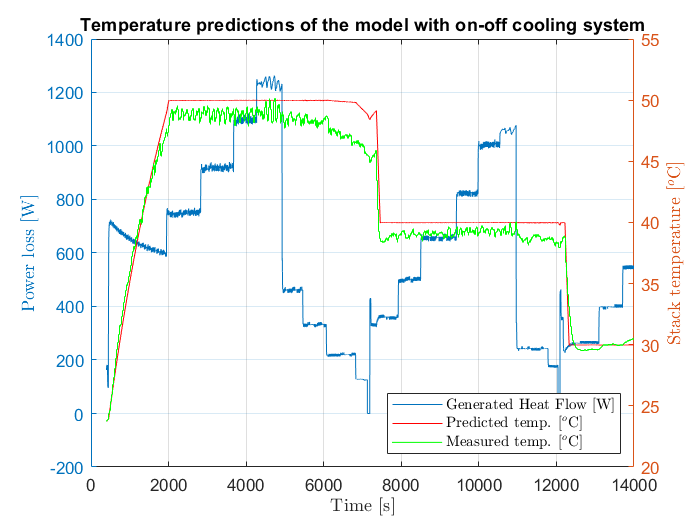

Qcool = 2900;
cth_begin = 400;
cth_end = 14000;
cth_measurements = m.time > cth_begin & m.time<cth_end;
Qloss = timeseries(m.Qloss(cth_measurements),m.time(cth_measurements));
RealTemp = timeseries(m.T(cth_measurements),m.time(cth_measurements));
T_amb =  timeseries(m.Tamb(cth_measurements)+CtoK,m.time(cth_measurements));
T_cool = ones(length(m.time(cth_measurements)),1); T_cool(1:7355) = 50; T_cool(7356:12215) = 40; T_cool(12215:end) = 30;
Tcool = timeseries(T_cool,m.time(cth_measurements)-cth_begin); %The cooling setting that we adjusted during the experiment

output = sim("Thermal_model.slx");

figure;
yyaxis left
plot(m.time(cth_measurements),m.Qloss(cth_measurements))
ylabel("Power loss [W]","Interpreter","latex")
hold on
yyaxis right
ylabel("Stack temperature [$^o$C]","Interpreter","latex")
plot(output.Model_Temp_Sim,"r")
plot(output.Real_Temp_Meas,"g-")
xlabel("Time [s]","Interpreter","latex")
title("Temperature predictions of the model with on-off cooling system")
grid on
hold off
legend("Generated Heat Flow [W]","Predicted temp. [$^o$C]","Measured temp. [$^o$C]","location","southeast","interpreter","latex")